try18_1 = load("08-22-24-18mM-try18-part1.mat");
try18_2 = load("08-22-24-18mM-try18-part2.mat");
try19 = load("08-23-18mM-try19.mat");
try20_1 = load('08-23-18mM-try20.mat');
try20_2 = load("08-23-18mM-try20b.mat");
try21 = load("10-21-2024.mat");
try22 = load("10-23-24-24mM.mat");
try23 = load("11-02-2024.mat");
try24 = load("11-6-24.mat");
try25_1 = load("11-10-24-part1.mat");
try25_3 = load("11-10-24-part3.mat");

try18_2.permeate_flowrate_filtered = lowpass(try18_2.permeate_flowrate_list, .1);
try19.permeate_flowrate_filtered = lowpass(try19.permeate_flowrate_list, .1);
try20_1.permeate_flowrate_filtered = lowpass(try20_1.permeate_flowrate_list, .1);
try20_2.permeate_flowrate_filtered = lowpass(try20_2.permeate_flowrate_list, .1);
try21.permeate_flowrate_filtered = lowpass(try21.permeate_flowrate_list, .1);
try22.permeate_flowrate_filtered = lowpass(try22.permeate_flowrate_list, .1);
try23.permeate_flowrate_filtered = lowpass(try23.permeate_flowrate_list, .1);
try24.permeate_flowrate_filtered = lowpass(try24.permeate_flowrate_list, .1);
try25_1.permeate_flowrate_filtered = lowpass(try25_1.permeate_flowrate_list, .1);
try25_3.permeate_flowrate_filtered = lowpass(try25_3.permeate_flowrate_list, .1);

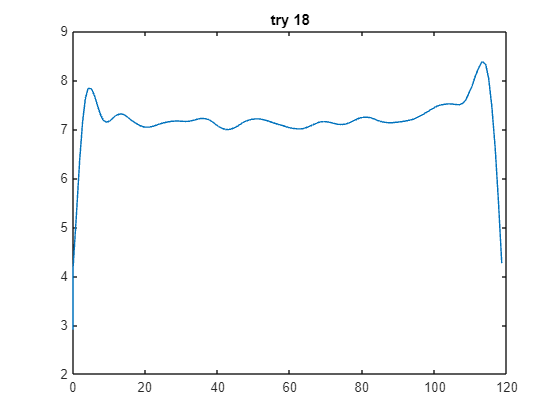

plot([try18_2.time_list(1:end-1)], [try18_2.permeate_flowrate_filtered])
title("try 18")

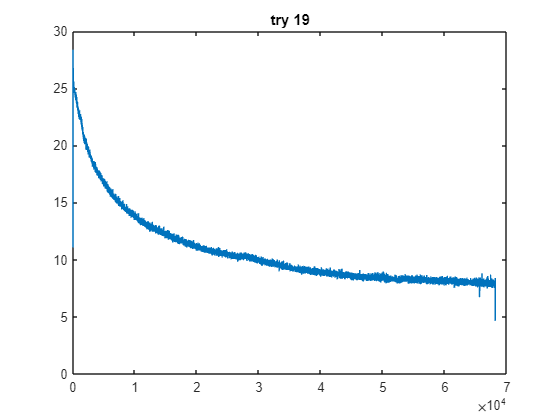

plot([try19.time_list(1:end-1)], [try19.permeate_flowrate_filtered])
title("try 19")

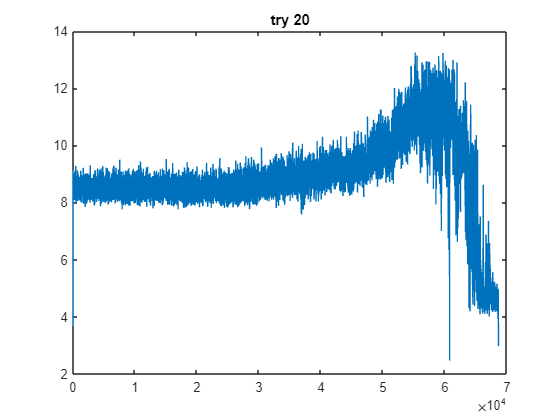

plot([try20_1.time_list(1:end-1);(try20_2.time_list(1:end-1)+try20_1.time_list(end))], [try20_1.permeate_flowrate_filtered;try20_2.permeate_flowrate_filtered])
title("try 20")

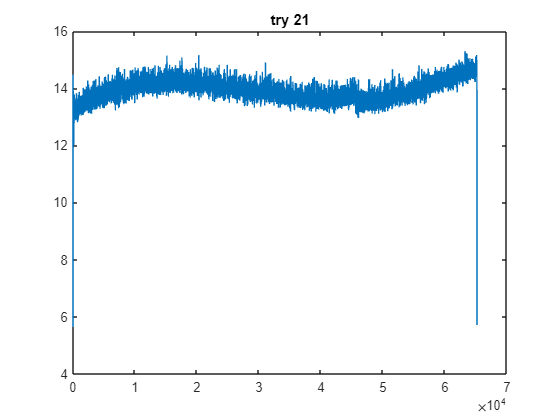

plot([try21.time_list(1:end-1)], [try21.permeate_flowrate_filtered])
title("try 21")

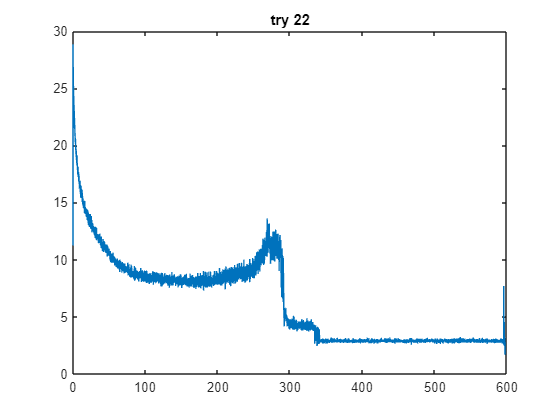

plot([try22.time_list(1:end-1)]/60, [try22.permeate_flowrate_filtered])
title("try 22")

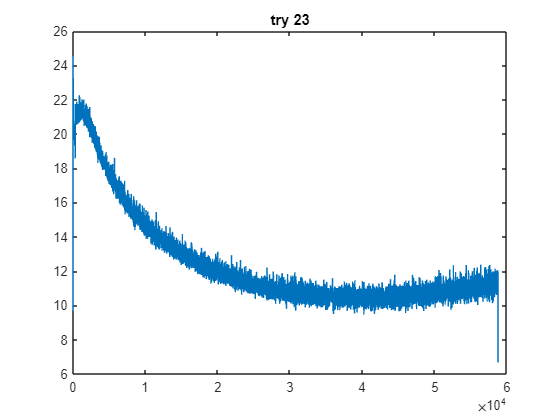

plot([try23.time_list(1:end-1)], [try23.permeate_flowrate_filtered])
title("try 23")

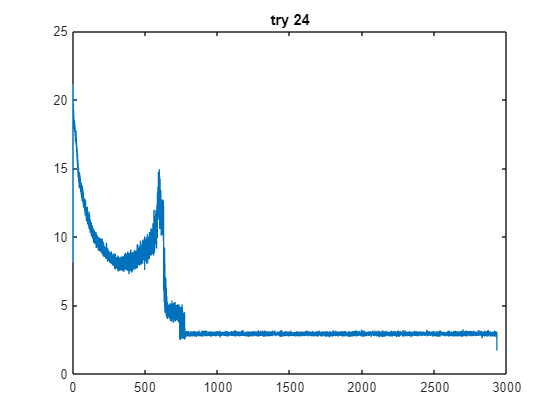

plot([try24.time_list(1:end-1)]/60, [try24.permeate_flowrate_filtered])
title("try 24")

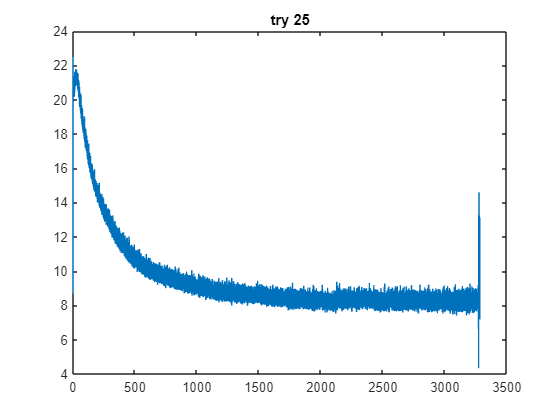

plot([try25_1.time_list(1:end-1);(try25_3.time_list(1:end-1)+try25_1.time_list(end))]/60, [try25_1.permeate_flowrate_filtered;try25_3.permeate_flowrate_filtered])
title("try 25")

try22.scaleTime = 285;
try24.scaleTime = 615;

try22.time_til_scale = try22.time_list(try22.time_list < try22.scaleTime*60);
try24.time_til_scale = try24.time_list(try24.time_list < try24.scaleTime*60);

try22.batch_flowrate_filtered = lowpass(try22.batch_flowrate_list(try22.time_list < try22.scaleTime*60),.1);
try24.batch_flowrate_filtered = lowpass(try24.batch_flowrate_list(try24.time_list < try24.scaleTime*60),.1);

Array indices must be positive integers or logical values.

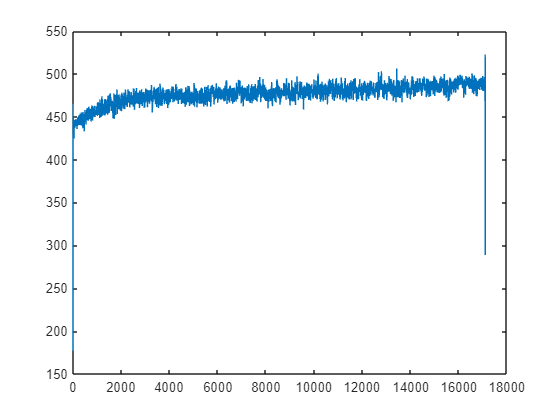

plot(try22.time_til_scale, try22.batch_flowrate_filtered)

mean(try22.batch_flowrate_filtered)

ans = 476.8089

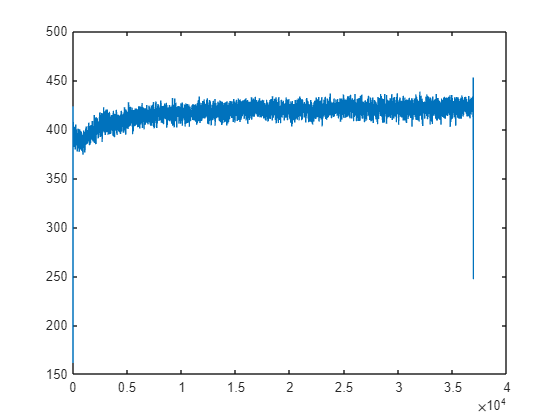

plot(try24.time_til_scale, try24.batch_flowrate_filtered)

mean(try24.batch_flowrate_filtered)

ans = 416.7664